# Final Project: Part 2, SIR Modeling of Historic *Hong Kong Flu*

**Fall 2021 - ENGR 25**

**Dr. Tess Weathers - tweathers@chabotcollege.edu**

**Final Project Completed by ****____Seth Miu & Darren Ho_____**

## **Background **

Relatively few flu sufferers die from the *Hong Kong Flu* or its complications, even without a vaccine. However, we may reasonably assume the number of excess deaths in a week was proportional to the number of new cases of flu in some earlier week. Thus, the figures reflect (proportionally) the rise and subsequent decline in the number of new cases of *Hong Kong Flu*.

At any given time during a flu epidemic, we want to know the number of people who are susceptible to the disease, are infected, or have recovered (SIR – Susceptible, Infected, Recovered). We typically assume that those who are infected or recovered are now immune to the disease. To simplify our model, we will include the dead amongst the recovered. We will also ignore the people who are born or die from non-flu cases or move in and out of the city during those weeks. The remainder of the population is still susceptible. With these assumptions, the fixed total population of New York City (approximately 7,900,000) may be divided into three categories:

- Those who are infected, **I(t)**

- Those who have recovered, **R(t)**

- Those who are still susceptible, **S(t)**

such that the independent variable ***t*** is time. We can normalize each of those functions by creating a second set of equations that represent the fraction of the total population in each category. If ***N ***is the total population, we have:

- **i(t) = I(t)/N**

- **r(t) = R(t)/N**

- **s(t) = S(t)/N**

## Instructions and Questions

Type up the answers to the following questions within the MATLAB Live Script. Answers should be written in clear, grammatically correct English without spelling errors.

### **Question 1: Model Introduction**

Under the assumptions we have made, answer the following questions.

#### 1a.

How do you think **s(t)** should vary with time? How should **r(t)** vary with time? How do you think** i(t)** should vary with time? It may help to sketch what you think the graph of each of these functions looks like.

We hypothesize that r(t) should continue to grow over time, growing at a rate dependant on i(t) (if i(t) is high, then r(t) should grow faster, plus vice versa).i(t) should probably grow up to a point, then maybe stay at that level or slowly decrease over time. During the early stages of an epidemic, s(t) should start off high (at 1), and then decrease over time - and as i(t) gets larger, s(t) should become smaller. 

#### 1b.

Explain why, at each time ***t***, **s(t) + i(t) + r(t) = 1**

  i(t), s(t), and r(t) are all used to show *percentages*. By dividing R(t) by N to get r(t), we're basically finding the ratio between the people who have recovered to the entire population. If R(t) = 37, and N = 50, then R(t) would say "there are 37 people who have recovered", while r(t) would say "74% of people (37x2) have recovered". The 3 lowercase functions are expressed in a decimal style, rather than a percent style. If they were in percent style, then the sum of the 3 would equal 100%. But instead, since they are represented as decimals, they add up to 1. 

### **Question 2: Each Variable Changes over Time**

Next, let’s make some assumptions about the rates of change of our dependent variables. No one is added to the susceptible group, since we ignore birth and migration. The only way an individual leaves the susceptible group is by becoming infected. The number of susceptibles depends on the number already susceptible, the number of individuals already infected and the contact between the two groups. Let us suppose that the coefficient beta, **β**, represents the contacts per day between the infected and the susceptible that are sufficient to spread the disease. If we assume homogeneous mixing of the populations, each infected individual generates **β * s(t) **new infected individuals per day.

We also assume that a fixed fraction, mu, **μ**, of the infected group will recover during any given day. For example, if the average duration of infection is three days, then, on average, one-third of the currently infected population recovers each day. We will ignore the “recovered” (non-infectious) people, for now, who still feel miserable, and might even die later from other complications. As a result, we have the following differential equations:

- The Susceptible Equation: $\frac{\textrm{ds}}{\textrm{dt}}=-\beta *s\left(t\right)*i\left(t\right)$

- The Recovered Equation: $\frac{\textrm{dr}}{\textrm{dt}}=\mu *i\left(t\right)$

- The Infected Equation: $\frac{\textrm{di}}{\textrm{dt}}=\beta *s\left(t\right)*i\left(t\right)-\mu *i\left(t\right)$

Answer the following questions in the space provided.

#### 2a. 

Explain why $\frac{\textrm{ds}}{\textrm{dt}}+\frac{\textrm{di}}{\textrm{dt}}+\frac{\textrm{dr}}{\textrm{dt}}=0$ ?

An analogy to this SIR system can be made to a pot full of water. As you pour water out of the pot and into the sink, water leaves the pot at the same rate that the water enters the sink at. It is the same concept here, where if a person gets infected, then there would be +1 person infected and -1 person not-infected, and 1 + -1 = 0. The same relationship can be made with di/dt and dr/dt, where if someone recovers, then it would be +1 person recovered and -1 person infected. On top of this, you cannot change i(t), s(t), or r(t), without changing another function (as in you can't change i(t) without changing s(t) or r(t)). People don't just disappear. 

This is a closed system and thus the rates of change acting on this population is zero-sum. Lastly you can use algebra to add the Susceptible, Recovered, Infected Equations to derive the expression above. 

#### 2b. 

Describe both components of the infected equation.

The infected equation can be formulated as the negation of the Supsceptible equation added to the Recovered equation. The relationship between the rates of change tells us that as the population of susceptible and recovered individials increases, the rate of infected individuals decreases (and vice versa). 

The first component refers to the number of possible people who can *become* infected. It  calculates this by using the number of physical interactions that infected and susceptible people make (Beta), then using this to decide how many people get infected due to these interactions.

The second component refers to the number of people who become *no longer* infected, aka the people who recover. It calculates this number by using mu (the fraction of people each day that should recover) and multiplying it by the number of infected people. 

#### 2c. 

What do the minus signs represent?

The minus signs represent the rate of change in people who "leave the group", or are no longer within the category (while the plus signs would represent the change in new people who "join the group"). 

### Question 3: Solving Model Differential Equations

Finally, we complete our model by giving each differential equation an initial condition. For this particular virus, hardly anyone was immune, so almost everyone was susceptible. That would suggest **s(0)** = 1. We will assume there was a trace level of infection in the population, say, 10 people. This is essentially zero, so we can assume **i(0) **= 0 and **r(0) **= 0. We don’t know the values for the parameters **μ** and **β**. We can estimate them, and then adjust them as necessary to fit the excess death rate. We estimated the average period of infectiousness as three days. That would suggest **μ** = 1/3. If we guessed that each infected person would make an infected contact every two days, then** β** = 1/2.

The following program simulates the effects of the virus on the populations of New York City. This is the same thing as solving a system of differential equations. 

#### 3a. 

Copy, paste and save this function as its own function file. You must also remove the leading comments.

% function dpop = SIRmodel(t,pop,b,u) % this is the function header
% s = pop(1);		% pop(1) is the input susceptible population 
% i = pop(2);		% pop(2) is the input infected population
% r = pop(3);		% pop(3) is the input recovered population	
% dpop=[ 	 % dpop is the rate of change of each of the population variables
%    - b*s*i; % this the equation for the rate of change of s, b is beta	
%    (b*s*i - u*i); % this the equation for the rate of change of i, u is mu 
%    u*i];		% this the equation for the rate of change of r
% end

#### 3b.

Run the function by executing the following code:

clear;clc;close all
nypop = 7900000; % population of New York at day 0 of the outbreak
pop0 = [1-(10/nypop),10/nypop,0];
mu = 1/3;
beta = 1/2;
SIRmodel([],pop0,beta,mu) % [] means we aren't yet plugging in a value for t

ans = 	1.0e+-6 *

   -0.6329
    0.2110
    0.4219


#### 3c.

What results do you get for dpop (the output of the SIRmodel)? Explain the significance of the positive and negative signs.

The output gives us: ds/dt = -0.6329 x 10^-6, di/dt = 0.2110 x 10^-6, dr/dt = 0.4219 x 10^-6.

The negative sign of ds/dt means that there are going to be less and less people within the s(t) group (susceptible group) initially 

The positive signs on di/dt and dr/dt imply that the trend of infected and recovered people will increase over time (with the latter being more prominent at the start of the outbreak)

#### 3d. 

Euler’s method is a numerical solution method for a system of differential equations. If we know **y****o** (i.e. **i(0)**, **r(0)**, and **s(0)**) and we have a way to calculate **dy/dt** at any point (***t***,***y***) (i.e. dpop), then it follows that we can calculate a sequence of y-values from the “slope and intercept equation”:


$$y_n =y_{n-1} +{\left(\frac{\textrm{dy}}{\textrm{dt}}\right)}_{n-1} *\Delta t$$


where $\Delta$t is a small change in time. For the SIR model, we want the dependent variables to be **s**, **i**, and **r**. Use the following script to apply Euler’s method to the SIR model function. Display a graphical solution of **s**, **i**, and** r** (POP(:,1), POP(:,2),POP(:,3)) on a single plot.

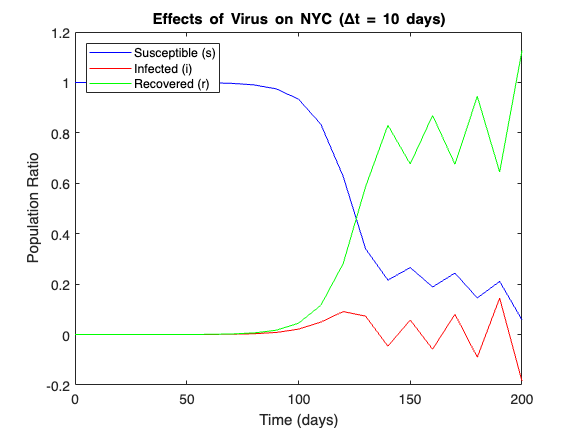

%Euler's Method
dt = 10;			% let delta t = 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan,POP(1,:),'b',tspan,POP(2,:),'r',tspan,POP(3,:),'g')
legend('Susceptible (s)','Infected (i)','Recovered (r)','Location','northwest')
title('Effects of Virus on NYC (\Deltat = 10 days)')
xlabel('Time (days)'),ylabel('Population Ratio')

#### 3e. 

Change $\Delta$**t** to **1** day and replot the solutions in the script below.

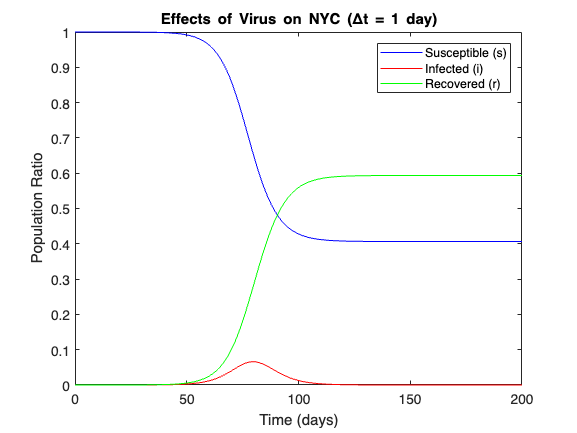

dt = 1;			        % let delta t= 1 day
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    		POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.

plot(tspan,POP(1,:),'b',tspan,POP(2,:),'r',tspan,POP(3,:),'g')
legend('Susceptible (s)','Infected (i)','Recovered (r)','Location','northeast')
title('Effects of Virus on NYC (\Deltat = 1 day)')
xlabel('Time (days)'),ylabel('Population Ratio')

#### 3f.

What observations do you have in comparison to the previous solution?

Using dt = 1 instead of dt = 10 lead to a much "smoother" graph. This also means that the results from solving the equation with a smaller differential leads to a continous solution that is less volatile compared to the initial parameters set for dt = 10.  

#### 3g.

*ode45* is a built-in ordinary differential equation solver. Implement the following code and replot the solutions. 

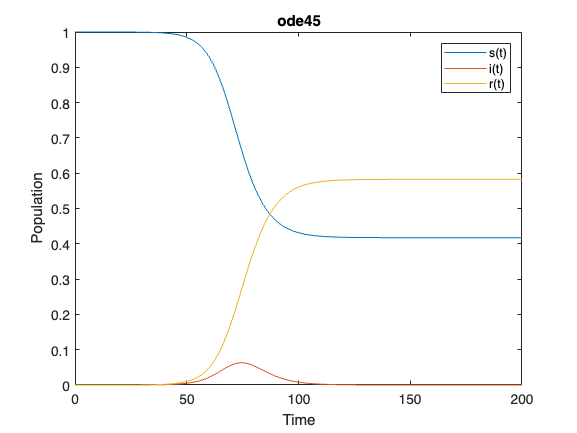

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45')
legend('s(t)','i(t)','r(t)')

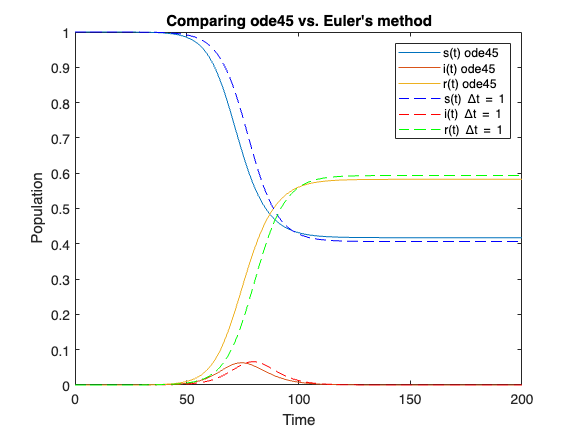


plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3)) 
hold on
plot(tspan,POP(1,:),'--b',tspan,POP(2,:),'--r',tspan,POP(3,:),'--g') 
hold off
xlabel('Time')
ylabel('Population')
title('Comparing ode45 vs. Euler''s method')
legend('s(t) ode45','i(t) ode45','r(t) ode45','s(t) \Deltat = 1', 'i(t) \Deltat = 1', 'r(t) \Deltat = 1')

What observations do you have in comparison to the previous solution?

Euler's method is a numerical method that approximates the solution of the differential equation that represents the SIR model of the NYC outbreak. Therefore it can be assumed that as dt approaches an infinitesimally small value, the solution would represent that of which is presented in ode45. 

As for raw comparisons between the 2 solutions both the ode45 and the dt = 1 models are nearly identical. However, the ode45 trends tend to change earlier than the dt = 1 lines (the peak of r(t) comes earlier with the ode45 line than the dt = 1 line, etc.). In addition to this, it seems as though there are more people who either recovered or never got infected, and less people who end infected, in ode45 than in the dt = 1.

#### 3h.

Take the output of the infected population and find its maximum over the region of interest. Plot the maximum **(as a separate marker) **on the previous figure.

% find the maximum of the infected population (both the value and the location in the array)
[maxval_Infect, maxindex]= max(pop(:,2))

maxval_Infect = 0.0629

maxindex = 75

maxInfectDay = tspan(maxindex)

maxInfectDay = 74

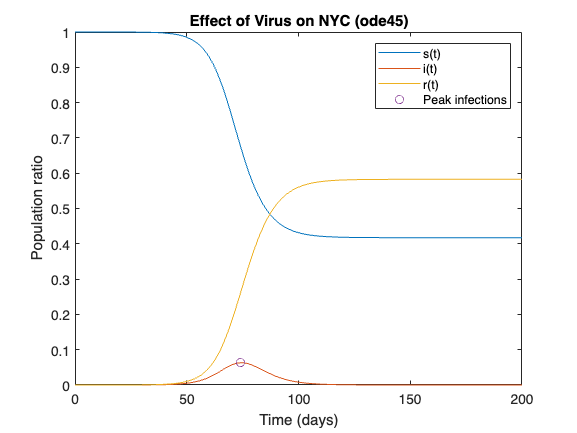

% plot the location and value of the maximum as a single (x,y) coordinate pair on the previous plot

plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
hold on
plot(maxInfectDay,maxval_Infect,'o')
hold off
xlabel('Time (days)')
ylabel('Population ratio')
title('Effect of Virus on NYC (ode45)')
legend('s(t)','i(t)','r(t)','Peak infections')

### Question 4: Sensitivity Analysis on Parameters

The value of **μ** is related to the flu’s infectious period and the value of **β **is an approximation of the flu’s “infectiousness”. Unfortunately, there is no way to directly observe **β**. Taken together, these values determine the disease’s spread. In reality, **μ** and **β** are a function of a city’s population, density, and “mixing rate”.

Let’s experiment with changes in **β**. Keep **μ** fixed at 1/3, and plot the graph of **i(t)** with several different values of **β** between 0.5 and 2.0.

#### 4a.

Use the slider in the script below to adjust **β. **You may also want to increase the interval of interest for time (tspan) to see the results for the lower levels of contact rate.

The code below also stores the peak levels of the infected population in an array and when they occur. Add a code to plot those results versus **β.**

beta = 1

beta = 1

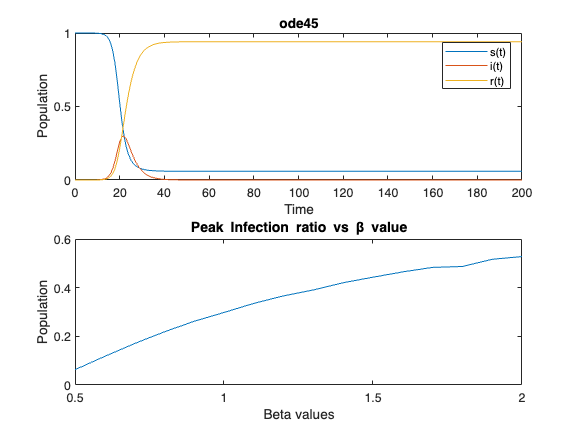

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45')
legend('s(t)','i(t)','r(t)')

% Below: Store values for peak ratio at different beta values
j = 1;
for i = 0.5:.1:2.0
    [t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,i,mu),tspan,pop0);
    [peak,loc] = max(pop(:,2));
    beta_n_peaks(j,:) = [i,peak];
    j=j+1;
end
subplot(2,1,2)

% Include a plot command to plot the beta value on the x-axis and the 
% corresponding peak infection ratio on the y-axis

plot(beta_n_peaks(:,1),beta_n_peaks(:,2)), 
xlabel('Beta values'), ylabel('Population')
title('Peak Infection ratio vs \beta value')

#### 4b.  

Describe how these changes in and tspan **β **you made in 4a above affect the graph of i(t) in the context of the SIR model.

Based off intuition, since Beta represents the contacts per day between infected and suspceptible individuals, as Beta increases (as the frequency of contacts increase) we would likely observe increase rates of infection which would increase the peak infection ratio within the population. Our sensitivity analyses supports those intuitions. 

Furthermore lower values of Beta actually "spreads" the infectious period over a greater time span whereas higher Beta values are "snuffed" out quicker in a shorter time span, albeit the higher values are accompanied by greater peaks. This is because our rate of recovery (mu) is fast enough for our population to be reslient towards the virus. In scenarios where Beta is low, the longevity of the virus within the given population can be prolonged due to the majority of the population being susceptible to the infection.

#### 4c.

Let’s experiment with a change in **μ**. Return **β **to 1/2. Use the slider below to change **μ** ranging from 0.1 to 0.6. You may also want to increase the interval of interest for time to see the results for the lower levels of contact rate.

#### 4d.

Store the peak levels of the infected population in an array and when they occur. To do this adapt the code above (create a loop) and plot** i(t)** with different values of **μ. **Then plot those results versus **μ.**

beta = 1/2

beta = 0.5000

mu = 0.35

mu = 0.3500

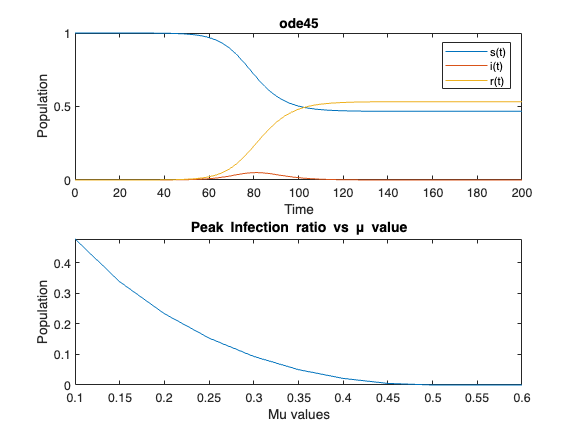

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45')
legend('s(t)','i(t)','r(t)')

% Create a loop to store peak levels of the infected population and when
% they occur (mu values). Hint: You can adapt the loop in the code above.

j = 1;
for M = 0.1:.05:0.6
    [t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,M),tspan,pop0);
    [peak,loc] = max(pop(:,2));
    mu_n_peaks(j,:) = [M,peak];
    j=j+1;
end

% Include a plot command to plot the mu value on the x-axis and the 
% corresponding peak infection ratio on the y-axis

subplot(2,1,2)
plot(mu_n_peaks(:,1),mu_n_peaks(:,2))
xlabel('Mu values'), ylabel('Population')
title('Peak Infection ratio vs \mu value')

#### 4e.

Describe how these changes in **μ **affect the graph of **i(t)** in the context of the SIR model.

The relationship between increasing values of mu and the infection ratio is inverse to that described in 4b. (infection ratio vs beta values). Since mu represents the "recovery" factor of the virus, we can observe within the sensitivity analysis that for greater values of mu (that is greater chances of recovering from the virus), there would be a higher population of those who are no longer able to spread or catch the virus and thus the peak infection ratio of the within the population is dimished.

#### 4f.

Create a subplot with an appropriately scaled plot of flu-related deaths **(our original data set from Part 1 with the deaths divided by 7900000)** with your model of the infected population **(i(t))**.

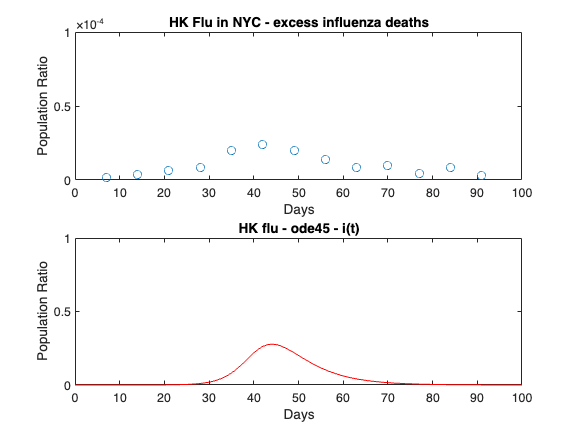

% Input different values of mu and beta:
mu = 0.178;
beta = 0.502;

% Data from Part 1:
death = [14 28 50 66 156 190 156 108 68 77 33 65 24];
weeks = 1:13;
% Plot the data and the model fit together:
figure
subplot(2,1,1)
plot(weeks*7,death/nypop,'o') % I multiplied weeks by seven to scale the the x-axis appropriately
title('HK Flu in NYC - excess influenza deaths')
xlabel('Days'),ylabel('Population Ratio')
ylim([0 .0001])

subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,2),'r')
ylim([0 1])
xlim([0 100])
xlabel('Days')
ylabel('Population Ratio')
title('HK flu - ode45 - i(t)')

#### 4g.

Which model parameters **(μ**,**β)** in the given range seem reasonable?  Explain your conclusion.

If we assume that the number of deaths caused by the flu is directly proportional to the number of infections, then our objective would be to find a range in which the model parameteres (μ,β) would most resemble and fit the curve of the HK flue deaths from part 1. As it is observed by our first subplot, the majority of deaths occur between days 25 to day 70, and the peak death ratio lies under 0.5 ^ 10^-4 (not a very deadly virus but we are only concerned about the ratio in this scenario).

We conclude that (μ = 0.175,β = 0.5) are reasonable estimates to model the HK flu, given the infection curves' resemblence to the "spread" and "peak" of deaths in our data.

### Question 5: Finding the Contact Number

The ratio of **β** to **μ**, is known as the contact number, **R****o**** = β / μ**. The contact number is a combined characteristic of the population and the disease. In similar populations, it measures the relative contagiousness of the disease, because it tells us indirectly how many the contacts are close enough to actually spread the disease. This formalism allows for the derivation of the following expression from $\frac{\textrm{di}}{\textrm{dt}}$ divided by $\frac{\textrm{ds}}{\textrm{dt}}$


$$i=-s+\frac{1}{R_o }\ln \left(s\right)+i\left(0\right)$$


which is a time-independent equation. There are two times when we know (or can estimate) the values of ***i*** and ***s***: at ***t ***= 0 and ***t*** = ∞. **i(0) **is approximately 0. Thus: 


$$i=-s+\frac{1}{R_o }\ln \left(s\right)$$


After a long time,** i(****∞****)** is approximately 0 again, and **s(****∞****)** is some constant. If there has been good reporting of the numbers who have contracted the disease, then


$$R_0 =\frac{{\ln \left(s\right)}_{\inf } }{s_{\inf } -1}$$


#### 5a.

Use one of your numerical solutions from Part 4 to estimate the value of** s(****∞****)**. Use this value to calculate the contact number **R****o** for the *Hong Kong Flu*. You may use the script window below if necessary.

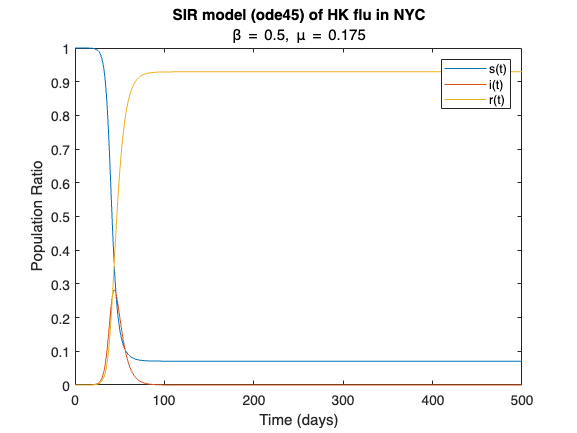

% Calculate Ro by estimating s at infinity, s(inf)

% time span approaching arbitrarily large # of days
tspan = 0:9999;

% utilize parameters fitted to Hong Kong flu (part 4f/4g)
beta = 0.5;
mu = 0.175;

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);

figure
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlim([0 500])
xlabel('Time (days)')
ylabel('Population Ratio')
title('SIR model (ode45) of HK flu in NYC','\beta = 0.5, \mu = 0.175')
legend('s(t)','i(t)','r(t)')


% The susceptible population ratio as time -> inf
sinf = min(pop(:,1)) 

sinf = 0.0707


Ro1 = log(sinf) / (sinf-1)

Ro1 = 2.8503

#### 5b.

Compare your calculated value with the one you get by direct calculation from the definition,** R****o**** = ****β****/ ****μ****.**

% Calculate Ro by using Ro = beta/mu

Ro2 = beta/mu

Ro2 = 2.8571

### Question 6: Using Vaccines to Prevent Epidemics

When experimenting with the relative sizes of **β** and **μ** in Part 4, you found that if **β **is small enough relative to **μ**, then no epidemic can develop. In the language of Part 5, if the contact number **R****o** is small enough, then there will be no epidemic. But another way to prevent an epidemic is to create herd immunity by reducing the initial susceptible population (**s****o**) artificially through inoculation.

The point of inoculation is to create herd immunity by stimulating in as many people as possible the antibodies that confer immunity without actually giving those people the disease. The fraction of the population that must be inoculated to obtain herd immunity will depend upon the contact number. Mathematically speaking, if:


$$i^{\prime } \left(0\right)=\mu *\left(R_0 *s_0 -1\right)\left(i_0 \right)$$


then as long **so** is less than **1/R****o**, the rate of change in the infectious population should be negative; and an epidemic will not occur.

#### 6a.

From 1912 to 1928, the contact number for measles in the U.S. was 12.8. If we assume that **R****o** is still 12.8 and that inoculation is 100% effective -- everyone inoculated obtains immunity from the disease -- what fraction of the population must be inoculated to prevent an epidemic?

% Use this space to calculate what fraction of the population must be
% inoculated at 100% effectiveness to prevent an epidemic

% Set i'(0) = 0 so that there is no growth rate of infections
% assumed that mu and i0 is non zero

Ro = 12.8

Ro = 12.8000

% initial susceptiple population ratio must be at least 
% (so value below) to prevent infectious growth
so = 1/Ro

so = 0.0781

% To prevent an epidemic spread, the innoculated
% population ratio (vacinnated %) must be greater than:
innoculated = 1 - so

innoculated = 0.9219

% in other words, the vacinnated % needs to be at least:
atleast = innoculated + 0.0001

atleast = 0.9220

#### 6b.

Suppose the vaccine is only 95% effective. What fraction of the population would have to be inoculated to prevent a measles epidemic?

% Use this space to calculate what fraction of the population must be
% inoculated at 95% effectiveness to prevent an epidemic


effective95 = atleast / 0.95

effective95 = 0.9705

## References

- David Smith and Lang Moore, "TheSIR Model for Spread of Disease - Herd Immunity" *Convergence *(December 2004)

- Gon, B. (2020, April26). Epidemic Modeling101: Or why your CoVID19exponential fits are wrong. Retrieved from https://medium.com/data-for-science/epidemic-modeling-101-or-why-your-covid19-expo nential-fits-are-wrong-97aa50c55f8